# Robot PKM

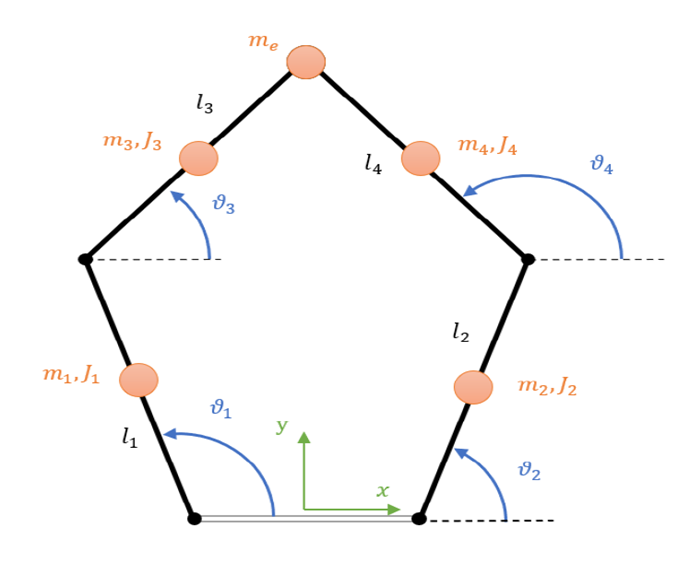

##   Definizione dati e informazioni utili manipolatore 

[PKM] = Define_Robot();

% Definizione parametri di test
theta1 = deg2rad(100); % Condizione iniziale posizione Theta1
theta2 = deg2rad(80); %  Condizione iniziale posizione Theta2
phi2 = deg2rad(0); % Angolo proprio della vite
phi1 = deg2rad(0);              % Posizione iniziale vite a riposo

theta1_p = 0; %  Condizione iniziale velocità theta1
theta2_p = 0; %  Condizione iniziale velocità tehta2
phi2_p = 0; % Velocita thetav di prova
phi1_p = 0;

theta1_pp = 0; %  Condizione iniziale accelerazione theta1
theta2_pp = 0; %  Condizione iniziale accelarazione theta2
phi2_pp = 0; % Accelerazione thetav di prova
phi1_pp = 0;

## Legge di moto

[Ldm_theta1,time] = Define_ldm(deg2rad(60), 'Sin') % Definisce una legge di moto data l'alzata in gradi per theta1

Error using Define_ldm
Too many output arguments.

[Ldm_theta2,time] = Define_ldm(deg2rad(70), 'Sin') % Definisce una legge di moto data l'alzata in gradi per theta2
[Ldm_phi2,time] = Define_ldm(deg2rad(0), 'pol357') % Definisce una legge di moto per la vite
[Ldm_phi1,time] = Define_ldm(deg2rad(0), 'pol357') % Definisce una legge di moto per l'altezza della vite

theta1ldm = theta1 + Ldm_theta1.moto.data{1,1}.v;
theta2ldm = theta2 + Ldm_theta2.moto.data{1,1}.v;
phi2ldm = phi2 + Ldm_phi2.moto.data{1,1}.v;
phi1ldm = phi1 + Ldm_phi1.moto.data{1,1}.v;

Theta = [theta1ldm; theta2ldm]

## Cinematica diretta

**Analisi di posizione**

[P, theta3, theta4, E1, E2] = Cinematica_Diretta_Posizione(PKM, theta1ldm, theta2ldm,time)

**Rappresentazione grafica**

%animation(PKM.link.d, PKM.link.l,theta1ldm,theta2ldm,theta3,theta4)

**Analisi di velocità**

theta1ldm_p = theta1_p + Ldm_theta1.moto.data{2,1}.v;
theta2ldm_p = theta2_p + Ldm_theta2.moto.data{2,1}.v;
phi2ldm_p = phi2_p + Ldm_phi2.moto.data{2,1}.v;
phi1ldm_p = phi1_p + Ldm_phi1.moto.data{2,1}.v;

[P_p, J, P_pM] = Cinematica_Diretta_Velocita2(PKM, theta1ldm, theta2ldm, theta1ldm_p,theta2ldm_p,P)
Theta_p = [theta1ldm_p;theta2ldm_p]
[theta3_p,theta4_p,J34] = Theta34p(PKM,theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p,time)

**Analisi di accelerazione**

theta1ldm_pp = theta1_pp + Ldm_theta1.moto.data{3,1}.v;
theta2ldm_pp = theta2_pp + Ldm_theta2.moto.data{3,1}.v;
phi2ldm_pp = phi2_pp + Ldm_phi2.moto.data{3,1}.v;
phi1ldm_pp = phi1_pp + Ldm_phi1.moto.data{3,1}.v;

Theta_pp = [theta1ldm_pp;theta2ldm_pp]
[P_pp] = Cinematica_Diretta_Accelerazione2(PKM,Theta, Theta_p, Theta_pp, P, P_p)
[theta3_pp,theta4_pp,J34p] = Theta34pp(theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p,...
    theta3_p,theta4_p,theta1ldm_pp, theta2ldm_pp,J34)

[C1_p, C2_p, C1_pp, C2_pp, E1_p, E1_pp, J1, J1p, J2, J2p, J3, J3p, J4, J4p, JE, JEp,P_p34, P_pp34] = Jacobiani(PKM, Theta, Theta_p, theta3, theta4, theta3_p, theta4_p, J34, J34p, P_pp, Theta_pp);

**Confronto cinematica analitica e derivata numerica**

%Plot_EF(PKM,P, P_p34, P_pp34, P_pM)

**Confronto cinematica matlab e adams**

% load PKM_PosEF
% load PKM_VelEF
% load PKM_AccEF
% load PKM_PosE1
% load PKM_VelE1
% load PKM_AccE1
% load PKM_Pa_VelCM
% time = linspace(0,PKM.ta,length(Theta_p));
%C1x_p_ad = PKM_Pa_VelCM(:,1);
% C1x_p_ad = C1x_p_ad';
% C1y_p_ad = PKM_Pa_VelCM(:,2);
% C1y_p_ad = C1y_p_ad';
% figure
% subplot(2,1,1);
%plot(time,C2_p(1,:)-C1x_p_ad,'color','b','linewidth',1)
% title('Errore velocità X C1 Matlab-Adams')
% grid on
% 
% subplot(2,1,2); 
% plot(time,C2_p(2,:)-C1y_p_ad,'color','b','linewidth',1)
% title('Errore velocità Y C1 Matlab-Adams')
% grid on
% Matlab_Adams_Cinematica(PKM_PosEF, P, PKM_VelEF, P_p, PKM_AccEF, P_pp, PKM_PosE1, E1, PKM_VelE1, E1_p, PKM_AccE1, E1_pp)
[V,V_p,V_pp,Jvite] = CinematicaVite(phi1ldm,phi2ldm,phi1ldm_p,phi2ldm_p,phi1ldm_pp,phi2ldm_pp);
plot(time,V)

## Cinematica Inversa

**Analisi di posizione**

[theta1inv,theta2inv] = Cinematica_Inversa_Posizione(P, PKM, theta1ldm, theta2ldm);
Errore_theta1 = theta1ldm - theta1inv;
Errore_theta2 = theta2ldm - theta2inv;


% figure
% subplot(2,1,1);
% plot(time,Errore_theta1,'color','b')
% title('Errore theta1')
% grid on
% subplot(2,1,2); 
% plot(time,Errore_theta2,'color','b')
% title('Errore theta2')
% grid on

**Rappresentazione grafica**

%animation(PKM.link.d, PKM.link.l,theta1inv,theta2inv,theta3,theta4)

**Analisi di velocità**

Theta_p_inv = Cinematica_Inversa_Velocita(J,P_p);

**Analisi di accelerazione**

% Theta_pp_inv = Cinematica_Inversa_Accelerazione(J_p,J,Theta_p,P_pp);

## Dinamica

**Metodo azioni vicolari**

%[C1_AV, C2_AV] = Dinamica(PKM,theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p,theta3_p,theta4_p,...
%    theta1ldm_pp,theta2ldm_pp,theta3_pp,theta4_pp,thetavldm_pp)

**Metodo PLV**

[C1_PLV, C2_PLV, M, K] = Dinamica_PLV(PKM,theta1ldm_p,theta2ldm_p,theta1ldm_pp,theta2ldm_pp,J1,J2,J3,J4,JE,J34,J1p,J2p,J3p,J4p,JEp,J34p)

**Confronto tra i due metodi**

%ErrC1 = C1_PLV(1,:)-C1_AV(1,:);
% ErrC2 = C2_PLV(1,:)-C2_AV(1,:);
% figure
% subplot(2,1,1);
% plot(time(1,:),C1_PLV(1,:),'color','b','linewidth',1)
% title('Coppia theta1 PLV')
% grid on
% subplot(2,1,2);
% plot(time(1,:),C2_PLV(1,:),'color','k','linewidth',1)
% title('Coppia theta2 PLV')
% grid on

**Confronto dinamica Matlab-Adams**

% load PKM_Pa_CoppieNOEF
% Matlab_Adams_Dinamica(PKM_Pa_CoppieNOEF, -C1_PLV, -C2_PLV)

**Dinamica inversa calcolo Coppie**

Condizioni = [theta1ldm(1,1),theta2ldm(1,1),theta1ldm_p(1,1),theta2ldm_p(1,1)]
[ThetaInt,Theta_pInt,Theta_ppInt] =  DinamicaInversa([C1_PLV;C2_PLV],Condizioni);

figure
plot(linspace(0,time(end),1000),C1_PLV)
hold on 
grid on
plot(linspace(0,time(end),1000),C2_PLV)
figure
plot(linspace(0,time(end),1000),Theta_ppInt(1,:))
hold on
grid on
plot(linspace(0,time(end),1000),theta1ldm_pp(1,:))
title('Confronto accelerazioni theta1')
figure
plot(linspace(0,time(end),1000),Theta_ppInt(2,:))
hold on
grid on
plot(linspace(0,time(end),1000),theta2ldm_pp(1,:))
title('Confronto accelerazioni theta2')
figure
plot(linspace(0,time(end),1000),Theta_pInt(1,:))
hold on
grid on
plot(linspace(0,time(end),1000),theta1ldm_p(1,:))
title('Confronto velocità theta1')
figure
plot(linspace(0,time(end),1000),Theta_pInt(2,:))
hold on
grid on
plot(linspace(0,time(end),1000),theta2ldm_p(1,:))
title('Confronto velocità theta2')

figure
plot(linspace(0,time(end),1000),ThetaInt(1,:))
hold on
grid on
plot(linspace(0,time(end),1000),theta1ldm(1,:))
title('Confronto posizione theta1')
figure
plot(linspace(0,time(end),1000),ThetaInt(2,:))
hold on
grid on
plot(linspace(0,time(end),1000),theta2ldm(1,:))
title('Confronto posizione theta2')

**Manipolabilità e punti di singolarità**

Singolarita(P,time,J)

**Dinamica Vite**

[Cvite] = DinamicaVite(Jvite,phi1ldm_pp,phi2ldm_pp);
figure
subplot(3,1,1)
%plot(linspace(0,time(end),1000),Cvite(1,:),"Color","red")
title('Coppia vite asse Z')
subplot(3,1,2)
%plot(linspace(0,time(end),1000),Cvite(2,:),"Color","b")
title('Coppia rotazione vite')
subplot(3,1,3)
%plot(linspace(0,time(end),1000),V(1,:),"Color","green")
title('Posizione vite')